# Discrete odd and even

clc;
clear all;
close all;

%we will show u(t)-u(t-10)
n=-15:1:15

n =    -15   -14   -13   -12   -11   -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15


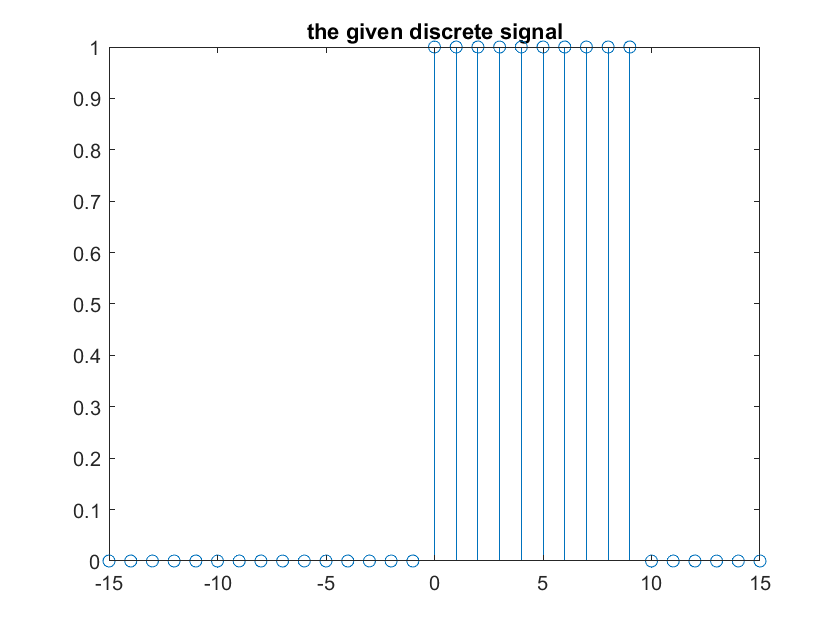

y1=[zeros(1,15),ones(1,10),zeros(1,6)];

y2=fliplr(y1);
subplot
stem(n,y1)
title('the given discrete signal');

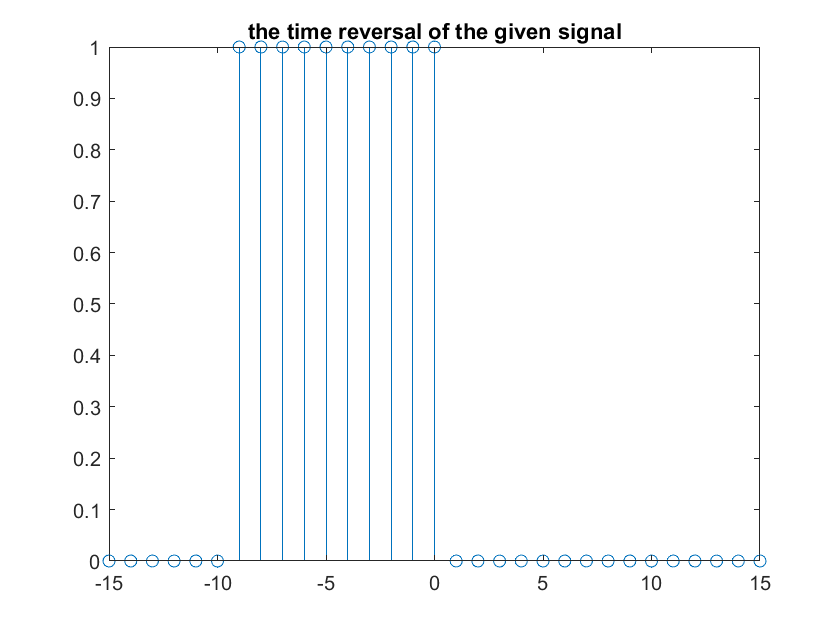

subplot
stem(n,y2)
title('the time reversal of the given signal');


if y1==y2
    disp('The signal is even')
else if y1==(-y2)
          disp('The signal is odd')
else disp('The signal is NONE')
end
end

The signal is NONE


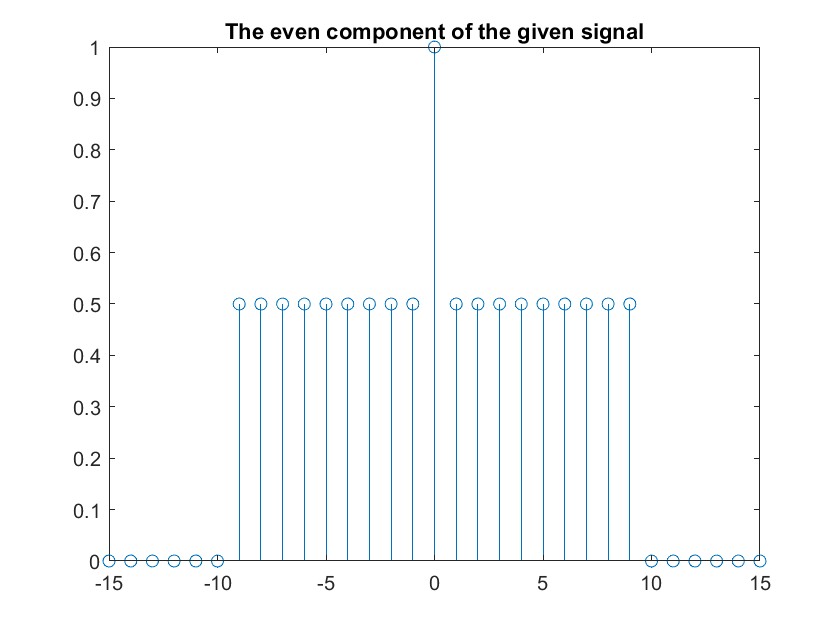


%to determine the odd and even component
ye=0.5*(y1+y2);
yo=0.5*(y1-y2);

stem(n,ye); title('The even component of the given signal');

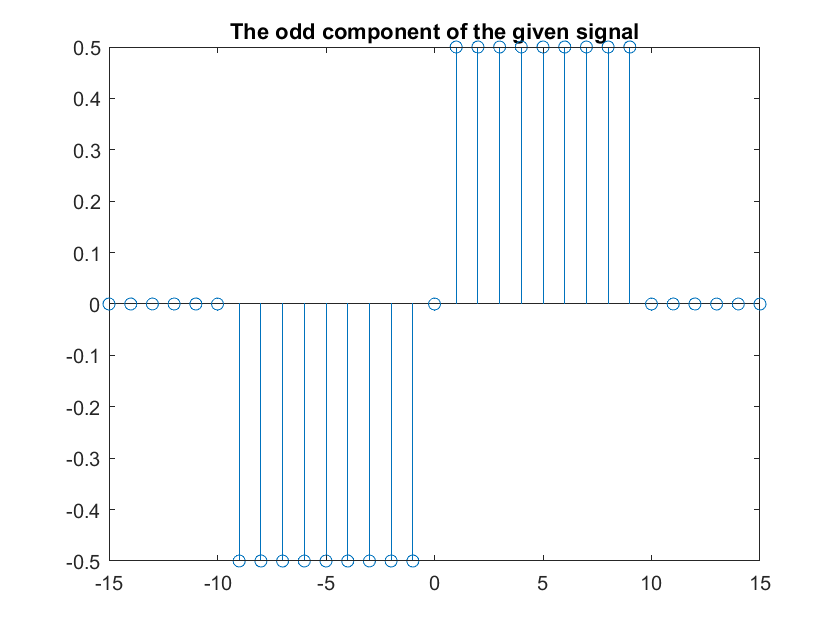

subplot;
stem(n,yo); title('The odd component of the given signal');